clear all, close all, clc
M350_F = readmatrix('M350_F.csv');
M350_R = readmatrix('M350_R.csv');
M2000_F = readmatrix('M2000_F.csv');
M2000_R = readmatrix('M2000_R.csv');
A50_F = readmatrix('A50_F.csv');
A50_R = readmatrix('A50_R.csv');
% M350_Fm = readmatrix('M350_Fm.csv');
% M350_Rm = readmatrix('M350_Rm.csv');
% M2000_Fm = readmatrix('M2000_Fm.csv');
% M2000_Rm = readmatrix('M2000_Rm.csv');
% A50_Fm = readmatrix('A50_Fm.csv');
% A50_Rm = readmatrix('A50_Rm.csv');


% peaks for cell 
M350_F_peaksb = cell(7*7,2);
M350_R_peaksb = cell(7*7,2);
M2000_F_peaksb = cell(7*7,2);
M2000_R_peaksb = cell(7*7,2);
A50_F_peaksb = cell(7*7,2);
A50_R_peaksb = cell(7*7,2);

M350_F_peaksa = zeros(7*7*2,12);
M350_R_peaksa = zeros(7*7*2,12);
M2000_F_peaksa = zeros(7*7*2,12);
M2000_R_peaksa = zeros(7*7*2,12);
A50_F_peaksa = zeros(7*7*2,12);
A50_R_peaksa = zeros(7*7*2,12);

M350_F_corrected = zeros(size(M350_F,1),size(M350_F,2));
M350_R_corrected = zeros(size(M350_F,1),size(M350_F,2));
M2000_F_corrected = zeros(size(M350_F,1),size(M350_F,2));
M2000_R_corrected = zeros(size(M350_F,1),size(M350_F,2));
A50_F_corrected = zeros(size(M350_F,1),size(M350_F,2));
A50_R_corrected = zeros(size(M350_F,1),size(M350_F,2));

M350_F_freq10mps = cell(7,1);
M350_R_freq10mps = cell(7,1);
M2000_F_freq10mps = cell(7,1);
M2000_R_freq10mps = cell(7,1);
A50_F_freq10mps = cell(7,1);
A50_R_freq10mps = cell(7,1);

%freq to remove
M350_F_freq10mps{1} = {[18.47 36.97 45.7 51.67 50 100 150] ; [18.47 44.23 138 50 100 150 ]; [18.47 27.73 44.23 51.6 50 100 150] ;[ 18.47 192 50 100 150] ;[18.47 27.73 44.23 51.6 50 100 150] ;[18.47 44.23 56.13 138 50 100 150 ];[18.47 27.73 44.57 50 100 150]};
M350_F_freq10mps{2} = {[18.47 45.73 51.6 50 100 150] ; [18.47 43.83 138 50 100 150 ]; [18.47 27.23 45.77 51.6 50 100 150] ;[ 18.47 192 50 100 150] ;[18.47 27.23 45.77 51.6 50 100 150] ;[18.47 43.83 55.87 138 50 100 150 ];[18.47 27.23 50 100 150]};
M350_F_freq10mps{3} = {[18.47 45.47 51.6 50 100 150] ; [18.47 43.63 138 50 100 150 ]; [18.47 27.2 45.47 51.53 50 100 150] ;[ 18.47 192.8 50 100 150] ;[18.47 27.2 45.47 51.53 50 100 150] ;[18.47 43.63 55.97 138 50 100 150 ];[18.47 27.2 50 100 150]};
M350_F_freq10mps{4} = {[18.43 44.86 51.43 50 100 150] ; [18.43 43.37 138 50 100 150 ]; [27.10 45.1 51.43 50 100 150] ;[ 18.43 27.1 192.8 50 100 150] ;[27.10 45.1 51.43 50 100 150] ;[18.43 43.37 55.7 138 50 100 150 ];[18.43 27.1 51.43 50 100 150]};
M350_F_freq10mps{5} = {[18.43 45 51.53 50 100 150] ; [18.43 43.1 138 50 100 150 ]; [26.93 45 51.53 50 100 150] ;[ 18.43 26.93 51.53 192.8 50 100 150] ;[26.93 45 51.53 50 100 150]  ;[18.43 43.1 55.73 138 50 100 150 ];[18.43 26.93 45.3 51.53 50 100 150]};
M350_F_freq10mps{6} = {[18.43 45.87 51.4 50 100 150] ; [18.43 43.03 137.8 50 100 150 ]; [26.87 44.7 51.4 50 100 150] ;[ 18.43 26.87 51.6 192.8 50 100 150] ;[26.87 44.7 51.4 50 100 150]  ;[18.43 43.03 55.93 137.8 50 100 150 ];[18.43 26.87 44.7 51.4 50 100 150]};
M350_F_freq10mps{7} = {[18.4 45.87 51.5 50 100 150] ; [18.4 42.73 138 50 100 150 ]; [26.93 44.27 51.5 50 100 150] ;[18.4 26.93 51.5 192.8 50 100 150] ;[26.93 44.27 51.5 50 100 150] ;[18.4 42.73 55.63 138 50 100 150 ];[18.4 26.93 44.27 51.5 50 100 150]};
%51 wala hat sakte the fixedc me 

M350_R_freq10mps{1} = {[18.4 41.93 51.067 50 100 150] ; [18.4 41.07 50 100 150 ]; [18.4 26.8 41.93 51.167 50 100 150] ;[ 18.4 50 100 150] ;[18.4 26.8 41.93 51.167 50 100 150] ;[18.4 41.07 50 100 150 ];[18.4 26.8 44.83 55.17 86.8 50 100 150]};
M350_R_freq10mps{2} = {[44.93 51.27 50 100 150] ; [18.4 39.9 44.77 55.4 138 50 100 150 ]; [26.73 44.93 51.267 50 100 150] ;[ 18.4 50 100 150] ;[26.73 44.93 51.267 50 100 150]  ;[18.4 39.9 44.77 55.4 138 50 100 150 ];[18.4 26.73 44.93 51.267 55.4 86.8 50 100 150]};
M350_R_freq10mps{3} = {[43.2 51.27 50 100 150] ; [18.43 40.9 138 50 100 150 ]; [26.83 43.2 51.267 50 100 150] ;[ 18.4 26.83 51.27 50 100 150] ;[26.83 43.2 51.267 50 100 150]  ;[18.43 40.9 138 50 100 150 ];[18.43 26.83 43.2 51.267 50 100 150]};
M350_R_freq10mps{4} = {[ 50 100 150] ; [18.47 40.87 138 50 100 150 ]; [26.53 43.07 50 100 150] ;[ 18.47 26.83 50 100 150] ;[26.53 43.07 50 100 150]  ;[18.47 40.87 138 50 100 150 ];[18.47 26.53 43.067 50 100 150]};
M350_R_freq10mps{5} = {[ 42.9 51.16 50 100 150] ; [18.43 40.7 55.66 138 50 100 150 ]; [26.6 42.9 51.167 50 100 150] ;[ 18.43 26.6 51.167 192.8 50 100 150] ;[26.6 42.9 51.167 50 100 150]  ;[18.43 40.7 55.66 138 50 100 150 ];[18.43 26.6 42.9 51.167 50 100 150]};
M350_R_freq10mps{6} = {[ 51.13 50 100 150] ; [18.4 40.5 55.5 138 50 100 150 ]; [26.57 42.63 51.13 50 100 150] ;[ 18.4 26.567 51.13 55.5 192.8 50 100 150] ;[26.57 42.63 51.13 50 100 150]  ;[18.4 40.5 55.5 138 50 100 150 ];[18.4 26.57 42.63 51.13 50 100 150]};
M350_R_freq10mps{7} = {[ 51.23 50 100 150] ; [18.23 40.6 55.5 138 50 100 150 ]; [26.6 42.6 51.23 50 100 150] ;[ 18.23 26.6 51.23 55.5 192.8 50 100 150] ;[26.6 42.6 51.23 50 100 150]  ;[18.23 40.6 55.5 138 50 100 150 ];[18.23 26.6 42.6 51.23 50 100 150]};

M2000_F_freq10mps{1} = {[18.47 36.93 45.47 51.63 50 100 150] ; [18.47 44.27 138 50 100 150 ]; [27.13 51.63 50 100 150] ;[18.47 192.8 50 100 150] ;[27.13 51.63 50 100 150];[];[18.47 50 100 150]};
M2000_F_freq10mps{2} = {[18.47 44.5 51.63 50 100 150] ; [18.43 44.23 138 50 100 150 ]; [27.2 45.73 51.63 50 100 150] ;[18.47 192.8 50 100 150] ;[27.2 45.73 51.63 50 100 150]; [18.43 44.23 55.87 138 50 100 150 ];[18.47 27.2 50 51.63 100 150]};
M2000_F_freq10mps{3} = {[18.43 45.3 51.57 50 100 150] ; [18.43 43.93 138 50 100 150 ]; [27.17 45.3 51.5 50 100 150] ;[18.43 192.8 50 100 150] ;[27.17 45.3 51.5 50 100 150]; [18.43 43.93 55.9 138 50 100 150 ];[18.43 36.86 50 51.63 100 150]};
M2000_F_freq10mps{4} = {[18.43 44.97 51.4 50 100 150] ; [18.43 43.5 138 50 100 150 ];  [27 44.97 51.4 50 100 150] ;[18.43 192.8 50 100 150] ;[27 44.97 51.4 50 100 150]; [18.43 43.5 56 138 50 100 150 ];[18.43 27 44.97 51.4 138 50 100 150]};
M2000_F_freq10mps{5} = {[44.6 51.47 50 100 150] ; [18.4 43.13 138 50 100 150 ];      [26.87 44.6 51.33 50 100 150] ;[18.4 192.8 50 100 150] ;[26.87 44.6 51.33 50 100 150]; [18.4 43.13 55.73 138 50 100 150 ];[18.4 26.87 44.6 51.33 138 50 100 150]};
M2000_F_freq10mps{6} = {[44.17 51.27 50 100 150] ; [18.43 42.97 138 50 100 150 ];     [27.07 44.17 51.27 50 100 150] ;[18.43 27.07 51.27 192.77 50 100 150] ;[27.07 44.17 51.27 50 100 150]; [18.43 42.97 55.8 138 50 100 150 ]; [18.43 27.07 44.17 51.53 138 50 100 150]}; % 51.53 in resu is diff from normal 51.27
M2000_F_freq10mps{7} = {[44.1 51.27 50 100 150] ; [18.4 42.43 138 50 100 150 ];     [26.73 43.87 51.27 50 100 150] ;[18.4 26.73 51.27 50 100 150] ;[26.73 43.87 51.27 50 100 150]; [18.4 42.43 55.83 138 50 100 150 ]; [18.4 26.73 43.87 138 51.27 50 100 150]};


M2000_R_freq10mps{1} = {[18.43 36.83 42.23 50.93 50 100 150] ; [18.43 25.17 38.37 43.6 138 50 100 150 ];[18.43 25.17 42.33 51 50 100 150] ;[18.43 192.73 50 100 150] ;[18.43 25.17 42.33 51 50 100 150]; [18.43 25.17 38.37 43.6 138 50 100 150 ]; [18.43 25.17 36.87 43.6 51.27 50 100 150]}; %extra peak at 25.17 38.37 in s 
M2000_R_freq10mps{2} = {[ 18.4 36.8 26.83 43.4 51.23 50 100 150] ; [ 18.4 33.23 40.87 138 50 100 150 ];[ 26.83 43.4 51.27 50 100 150] ;[ 18.4 26.83 51.27 50 100 150] ;[ 26.83 43.4 51.27 50 100 150]; [ 18.4 33.23 40.87 138 50 100 150]; [18.4 26.83 40.87 51.27 50 100 150]}; %33.23 EXTRA freq in S
M2000_R_freq10mps{3} = {[ 18.4 26.87 43.27 51.2 50 100 150] ; [ 18.4 41.07 138 50 100 150 ];[ 26.87 43.27 51.2 50 100 150] ;[ 18.4 26.87 51.2 192.77 50 100 150] ;[ 26.87 43.27 51.2 50 100 150]; [18.4 41.07 138 50 100 150 ]; [18.4 26.87 43.27 51.2 50 100 150]}; 
M2000_R_freq10mps{4} = {[18.43 26.73 43.37 51.3 50 100 150] ; [18.43 41.37 138 50 100 150 ];[26.73 43.37 51.3 50 100 150] ;[18.43 26.73 51.3 192.77 50 100 150] ;[26.73 43.37 51.3 50 100 150];  [18.43 41.37 138 50 100 150 ]; [18.43 26.73 41.37 43.37 51.3 138 50 100 150]}; 
M2000_R_freq10mps{5} = {[26.83 43.47 51.23 50 100 150] ; [18.43 41.1 138 50 100 150 ];[26.83 43.47 51.23 50 100 150] ;[18.43 26.83 51.1 192.73 50 100 150] ;[26.83 43.47 51.23 50 100 150];[18.43 41.1 138 50 100 150 ]; [18.43 26.83 41.1 43.47 51.23 50 100 150]}; 
M2000_R_freq10mps{6} = {[26.7 43.33 51.03 50 100 150] ; [18.43 43.33 138 50 100 150 ];[26.7 43.27 51.03 50 100 150] ;[18.43 26.7 51.03 50 100 150] ;[26.7 43.27 51.03 50 100 150]; [18.43 43.33 138 50 100 150 ]; [18.43 26.7 43.27 51.03 50 100 150]}; %extra 40.63 peak in every data
M2000_R_freq10mps{7} = {[26.57 42.56 51.07 50 100 150] ; [18.5 42.57 138 50 100 150 ];[26.57 42.57 51.07 50 100 150] ;[18.5 26.57 51.07 50 100 150] ;[26.57 42.57 51.07 50 100 150] ;[18.5 42.57 138 50 100 150]; [18.5 26.57 42.57 51.07 138 50 100 150]}; %extra 40.3 peak in every data


A50_F_freq10mps{1} = {[18.37 27.13 36.73 46.03 51.83 50 100 150] ; [18.37 44.67 138 50 100 150 ];[27.17 46.03 51.83 50 100 150] ;[18.37 193.03 50 100 150] ;[27.17 46.03 51.83 50 100 150];[18.37 44.67 138 50 100 150 ]; [18.37 27.17 50 100 150]}; %extra peak at 149.53 in every data (prob current data)
A50_F_freq10mps{2} = {[18.37 27.03 45.7 51.6 50 100 150] ; [18.37 44.4 138 50 100 150 ];[27.03 45.7 51.6 50 100 150] ;[18.37 27.03 193.07 50 100 150] ;[27.03 45.7 51.6 55.9 50 100 150];[18.37 44.4 55.9 138 50 100 150 ]; [18.37 27.03 44.4 51.6 50 100 150]}; %extra peak at 149.63 in every data
A50_F_freq10mps{3} = {[18.4 26.93 45.4 51.5 50 100 150] ; [18.4 44 138 50 100 150 ];[26.93 45.4 51.5 50 100 150];[18.4 26.93 51.5 193.03 50 100 150] ;[26.93 45.4 51.5 50 100 150];[18.4 44 56.03 138 50 100 150 ];[18.4 26.93 45.4 51.6 50 100 150]}; 
A50_F_freq10mps{4} = {[26.83 45.3 51.47 50 100 150];[18.4 43.77 138 50 100 150 ];[26.83 45.07 51.47 50 100 150];[18.4 26.83 51.47 193.03 50 100 150] ;[26.83 45.07 51.47 50 100 150];[18.4 43.77 55.9 138 50 100 150];[18.4 26.83 45.07 51.47 50 100 150]}; 
A50_F_freq10mps{5} = {[ 26.6 44.47 51.33 50 100 150];[18.27 43.37 138 50 100 150];[26.6 44.47 51.33 50 100 150];[ 18.27 26.6 51.33 193.03 50 100 150] ;[26.6 44.47 51.33 50 100 150];[18.27 43.37 56.07 138 50 100 150];[18.27 26.6 44.47 51.33 50 100 150]}; 
A50_F_freq10mps{6} = {[26.27 43.9 51.4 50 100 150];[18.33 42.97 138 50 100 150];[26.27 43.9 51.4 50 100 150];[ 18.33 26.27 51.4 193.03 50 100 150] ;[26.27 43.9 51.4 50 100 150];[18.33 42.97 55.47 138 50 100 150];[18.33 26.27 43.9 51.4 50 100 150]}; 
A50_F_freq10mps{7} = {[26.1 43.33 51.13 50 100 150];[17.9 41.67 137 50 100 150];[26.1 43.2 51.13 50 100 150];[17.9 26.1 51.13 193.07 50 100 150] ;[26.1 43.2 51.13 50 100 150];[17.9 41.67 55.53 137 50 100 150];[17.9 26.1 43.2 51.13 50 100 150]}; 


A50_R_freq10mps{1} = {[18.4 26.73 36.8 42.4 50.97 50 100 150] ; [18.4 39.93 43.73 50 100 150 ];[18.4 26.73 42.4 50.97 50 100 150] ;[18.4 193.13 50 100 150] ;[18.4 26.73 42.4 50.97 50 100 150];[18.4 39.93 43.73 50 100 150 ]; [18.4 26.73 50 100 150]}; %extra peak at 39.73 in S
A50_R_freq10mps{2} = {[18.4 26.83 41.67 43.73 51.23 50 100 150] ; [18.4 41.4 138 50 100 150 ];[26.83 41.67 43.73 51.23 50 100 150] ;[18.4 26.83 193.1 50 100 150] ;[26.83 41.67 43.73 51.23 50 100 150] ;[18.4 41.4 138 50 100 150 ]; [18.4 41.4 50 100 150]}; %extra peak at 43.73 in N
A50_R_freq10mps{3} = {[18.4 26.53 43.9 51.2 50 100 150];[18.4 42.2 138 50 100 150];[26.53 43.73 51.2 50 100 150];[18.4 26.53 193.1 50 100 150];[26.53 43.73 51.2 50 100 150];[18.4 42.2 138 50 100 150];[18.4 26.53 43.73 51.2 50 100 150]}; %60.37 in Ax extra(not removed)
A50_R_freq10mps{4} = {[26.53 43.33 50.93 50 100 150];[18.27 136 50 100 150];[26.53 43.33 50.93 50 100 150];[18.27 26.53 193.07 50 100 150];[26.53 43.33 50.93 50 100 150];[18.27 136 50 100 150];[18.27 26.53 50 100 150]}; 
A50_R_freq10mps{5} = {[26.47 43.37 51.1 50 100 150];[18.27 41.27 137 50 100 150];[26.47 42.93 51.1 50 100 150];[18.27 26.47 42.93 51.1 193.03 50 100 150];[26.47 42.93 51.1 50 100 150];[18.27 41.27 137 50 100 150];[18.27 26.47 41.27 42.93 51.1 50 100 150]};
A50_R_freq10mps{6} = {[26.2 42.9 51.1 50 100 150];[18.1 40.7 137 50 100 150];[26.2 42.9 51.1 50 100 150];[18.1 26.2 42.73 51.1 193.03 50 100 150];[26.2 42.9 51.1 50 100 150];[18.1 40.7 137 50 100 150];[18.1 26.2 40.7 42.9 51.1 50 100 150]};
A50_R_freq10mps{7} = {[25.93 42.5 51 50 100 150];[18.03 40.33 137 50 100 150];[25.93 42.5 51 50 100 150];[18.03 25.93 41.6 51 50 100 150];[25.93 42.5 51 50 100 150];[18.03 40.33 137 50 100 150];[18.03 25.93 41.6 51 50 100 150]};
%A50_R_freq10mps{7} = {[50 100 150];[50 100 150];[50 100 150];[50 100 150];[50 100 150];[50 100 150];[50 100 150]};


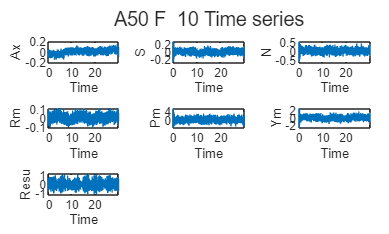

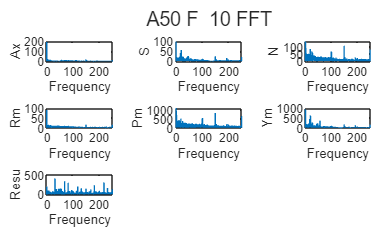

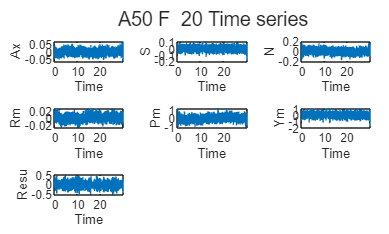

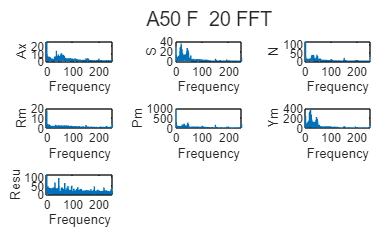

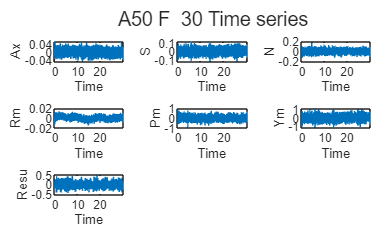

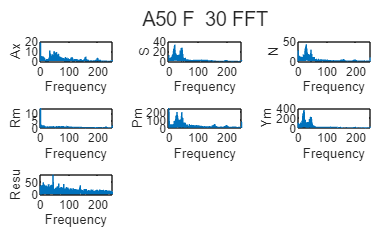

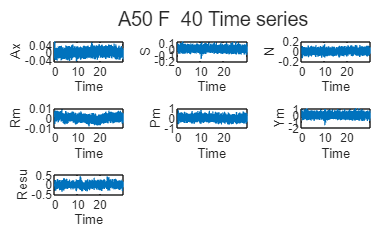

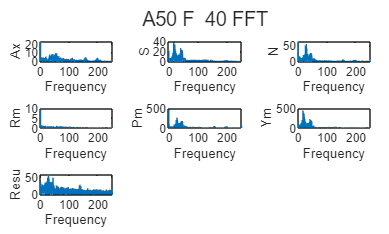

%remove freq code (run this 6 times)
ImageFolder ='D:\IITK\Projects\Prof Mittal\New experiment\00_Shuttlecock_Aarush\Write\Time Series\Time Series Write\Plots\Removed freq plots';

for i = 1:7
%i = 7;
    [A50_F_peaksb,A50_F_corrected((i-1)*9 + (3:9),:)] = removef(A50_F((i-1)*9 + (3:9),:) , A50_F_freq10mps{i},"A50 F ",i,A50_F_peaksb,ImageFolder);
end

%finding mean s
% M350_Fm = findm(M350_F_corrected);
% M350_Rm = findm(M350_R_corrected);
% M2000_Fm = findm(M2000_F_corrected);
% M2000_Rm = findm(M2000_R_corrected);
A50_Fm = findm(A50_F_corrected);
A50_Rm = findm(A50_R_corrected);

for i = 1:size(M350_R_peaksb,1)
    
    M350_F_peaksa((i-1)*2 + (1:2),:) = sortm(M350_F_peaksb(i,:));
   

    M350_R_peaksa((i-1)*2 + (1:2),:) = sortm(M350_R_peaksb(i,:));
 
    M2000_F_peaksa((i-1)*2 + (1:2),:) = sortm(M2000_F_peaksb(i,:));
 
    M2000_R_peaksa((i-1)*2 + (1:2),:) = sortm(M2000_R_peaksb(i,:));
   
    A50_F_peaksa((i-1)*2 + (1:2),:) = sortm(A50_F_peaksb(i,:));
 
    A50_R_peaksa((i-1)*2 + (1:2),:) = sortm(A50_R_peaksb(i,:));

end